**Item a), b)**

clear all;clc;close all;
s = tf('s');

optionss=bodeoptions;
optionss.MagVisible='on';
optionss.PhaseMatching='on';
optionss.PhaseMatchingValue=-180;
optionss.PhaseMatchingFreq=1;
optionss.Grid='on';

analizo lo realizado a mano a ver si con lo realizado llego a un mf=60 

grados

P = (s+2)^2/(s*(s-4)^2)

P =
 
    s^2 + 4 s + 4
  ------------------
  s^3 - 8 s^2 + 16 s
 
Continuous-time transfer function.



k=1

k = 1

C = k*(s+4)/s

C =
 
  s + 4
  -----
    s
 
Continuous-time transfer function.



L=C*P

L =
 
  s^3 + 8 s^2 + 20 s + 16
  -----------------------
   s^4 - 8 s^3 + 16 s^2
 
Continuous-time transfer function.



Realizo el diagrama de Bode de L con k=1 para determinar a qué valor de k cumple con MF=60 grados

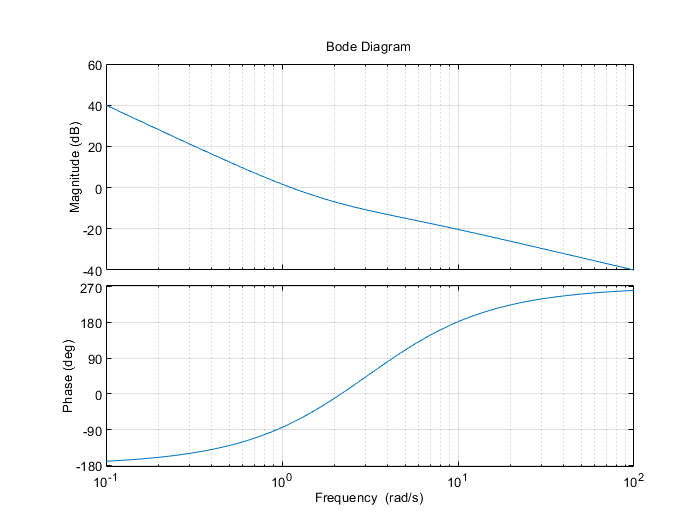

bode(L,optionss)

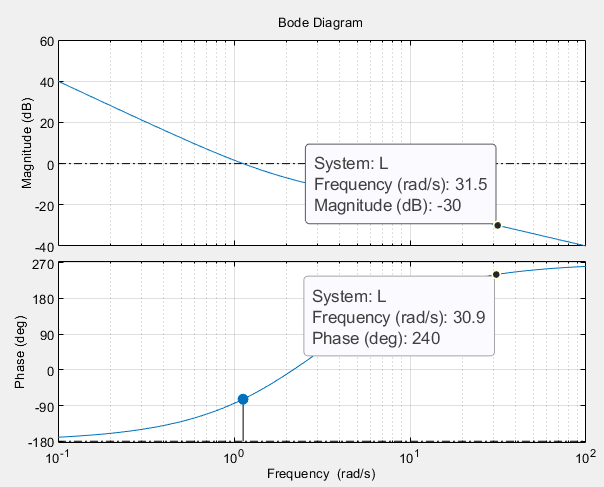

Se observa que para k= 30dB se cumple con el margen de fase deseado.

k2=db2mag(30)

k2 = 31.6228

C2=k2*(s+4)/s

C2 =
 
  31.62 s + 126.5
  ---------------
         s
 
Continuous-time transfer function.



L2=C2*P

L2 =
 
  31.62 s^3 + 253 s^2 + 632.5 s + 506
  -----------------------------------
         s^4 - 8 s^3 + 16 s^2
 
Continuous-time transfer function.



%bode(L2,optionss)

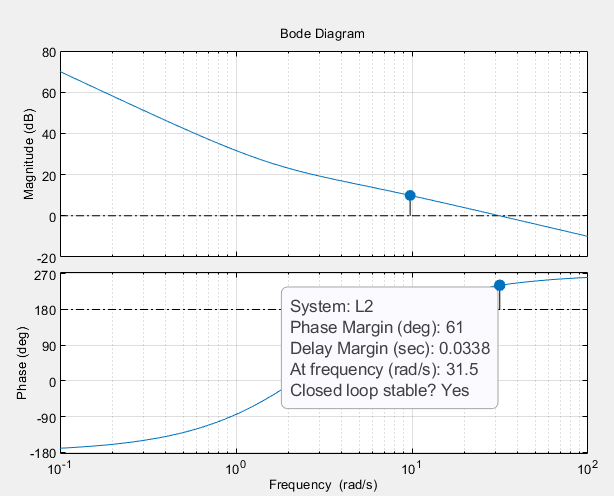

Se nota que el margen de fase es de 61 grados, lo cual se considera aceptable en nuestro caso. Lo que cambió con respecto al original fue el valor de "k", ya que anteriormente no lo había calculado.

**Item c)**

Se realizan iteraciones tal de encontrar el ts que no me reste mas de 5 grados de mf.

T = [0.1 0.22 0.01 0.005 0.004 0.003 0.002 0.001];

% 
% figure()
% bode(L2, optionss, 'black');
% grid on
% hold on
% for i=1:length(T)
%     T(i)
%     Pad=(1-T(i)/4*s)/(1+T(i)/4*s);
%     bode(L2*Pad, optionss)
% end
% 
% legend('L', '0.1', '0.22',' 0.01 ','0.005 ','0.004 ','0.003 ','0.002 ','0.001')
% hold off

A continuación se observa que para T=0.005, me decrece en 5 grados el margen de fase. Se utilizará dicho valor. 

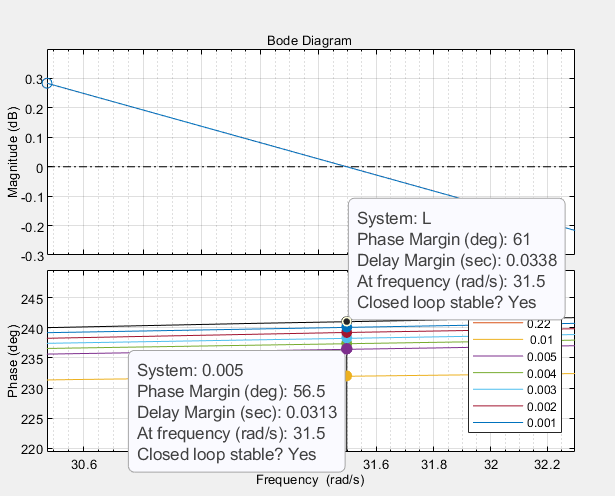

Ahora, hace falta recalibrar el valor de "k" para así mantener el margen de fase en 60 grados.

k_aux=1

k_aux = 1

c_aux=k_aux*(s+4)/s

c_aux =
 
  s + 4
  -----
    s
 
Continuous-time transfer function.



pade=(1-0.005/4*s)/(1+0.005/4*s)

pade =
 
  -0.00125 s + 1
  --------------
  0.00125 s + 1
 
Continuous-time transfer function.



L_aux=c_aux*P*pade

L_aux =
 
  -0.00125 s^4 + 0.99 s^3 + 7.975 s^2 + 19.98 s + 16
  --------------------------------------------------
      0.00125 s^5 + 0.99 s^4 - 7.98 s^3 + 16 s^2
 
Continuous-time transfer function.



%bode(L_aux, optionss)

Se observa que se cumple el mf=60 con un k=31,3db

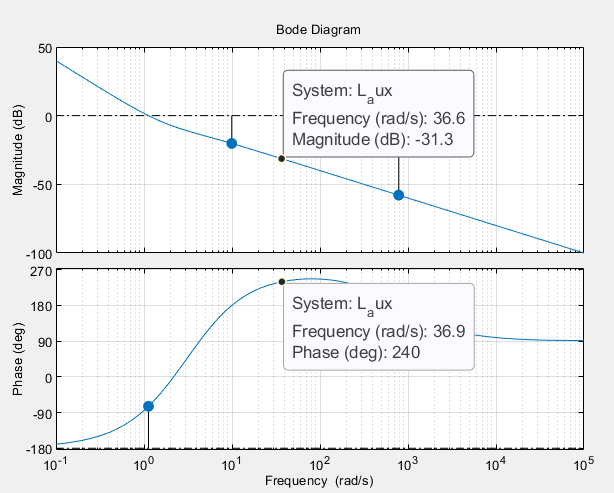

k_final=db2mag(31.3)

k_final = 36.7282

c_final=k_final*(s+4)/s

c_final =
 
  36.73 s + 146.9
  ---------------
         s
 
Continuous-time transfer function.



pade=(1-0.005/4*s)/(1+0.005/4*s)

pade =
 
  -0.00125 s + 1
  --------------
  0.00125 s + 1
 
Continuous-time transfer function.



L_final=c_final*P*pade

L_final =
 
  -0.04591 s^4 + 36.36 s^3 + 292.9 s^2 + 733.8 s + 587.7
  ------------------------------------------------------
        0.00125 s^5 + 0.99 s^4 - 7.98 s^3 + 16 s^2
 
Continuous-time transfer function.



%bode(L_final, optionss)

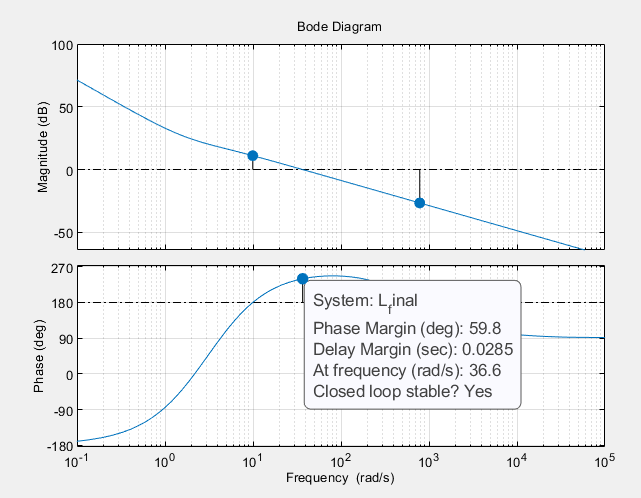Se puede apreciar que el MF=59,8 grados, por lo que se concluye que el valor de sampling rate T elegido es correcto.

**Item d) es en SIMULINK**

Cd=c2d(c_final,0.005,'tustin')

Cd =
 
  37.1 z - 36.36
  --------------
      z - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



**Item e)**

Grafico el grupo de las 4: 

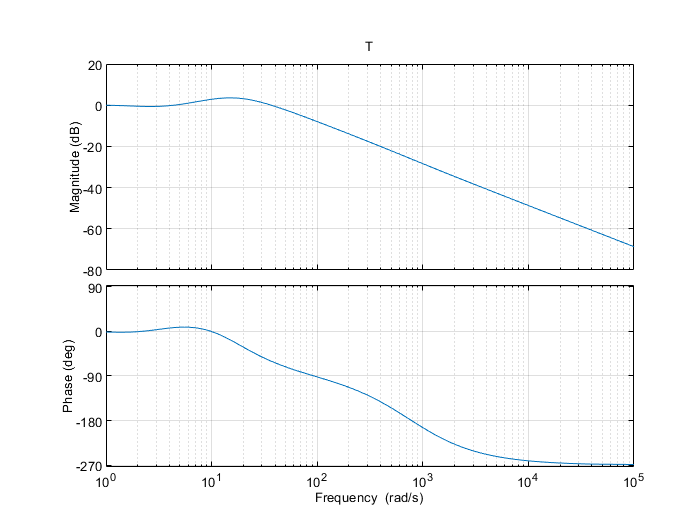

T_transf = minreal(L_final/(1+L_final)); 
figure() 
bode(T_transf,optionss);title('T');

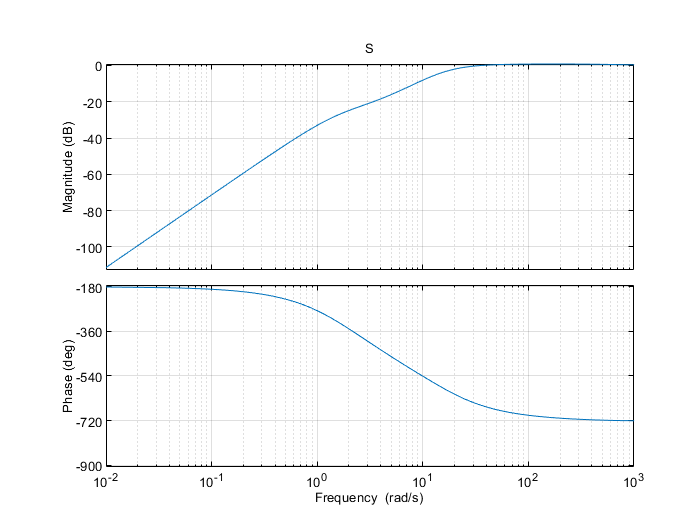

S_transf = 1 - T_transf;  
figure()
bode(S_transf,optionss);title('S');

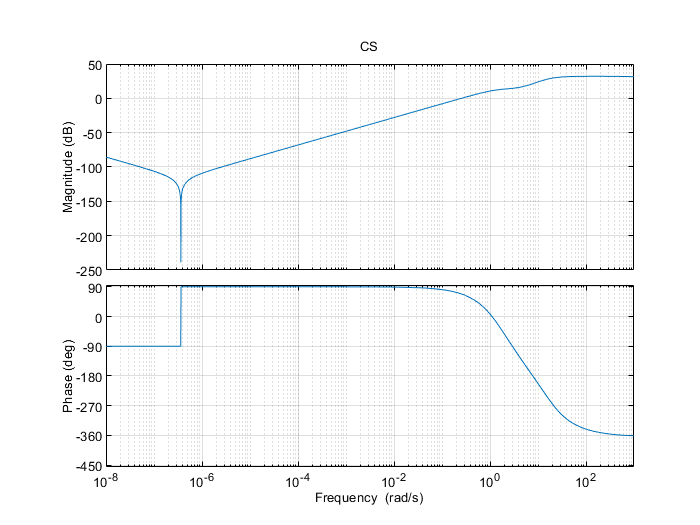

CS = minreal(c_final*S_transf); 
figure()
bode(CS,optionss);title('CS');

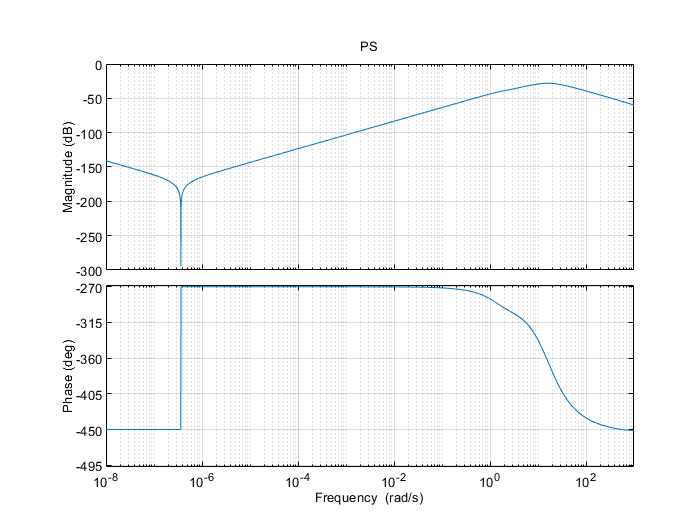

PS = minreal(P*S_transf);
figure()
bode(PS,optionss);title('PS');

Ahora grafico la respuesta al escalón y la perturbación a la entrada:

*Respuesta al escalón*

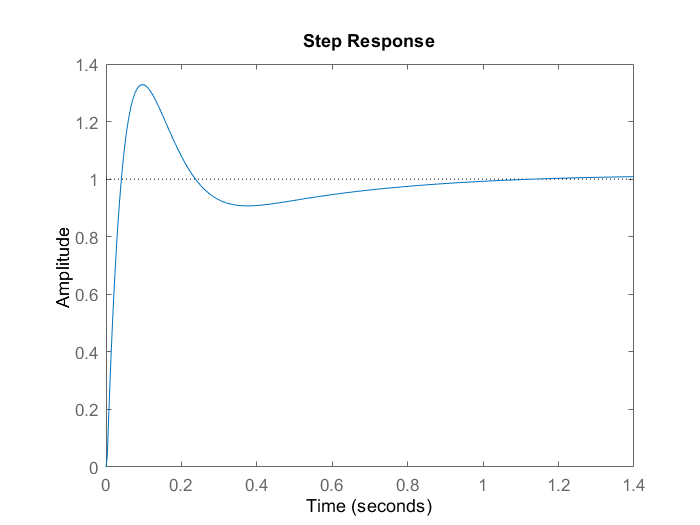

figure()
step(T_transf);

*Rta a perturbación de  entrada:*

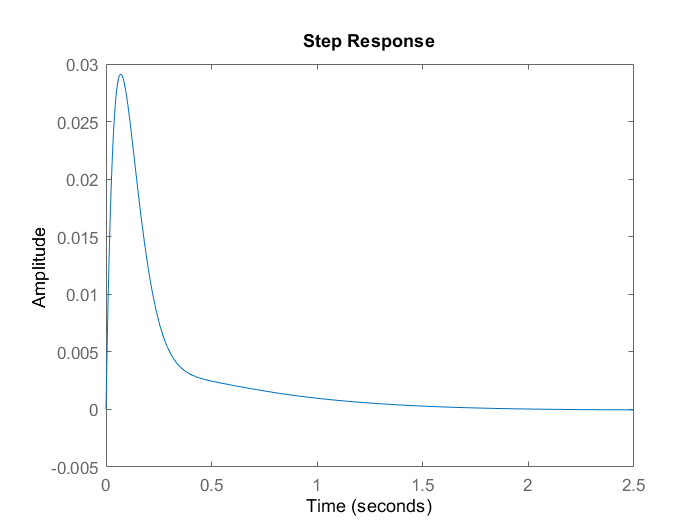

figure()
step(PS);

Se observa que para ambos casos, la respuesta se estabiliza bastante rápido.

**Item F)**

El margen de fase ya fue calculado anteriormente. Para el caso de margen de ganancia de amplitud, basta con observar el mismo gráfico visto al final del item C):

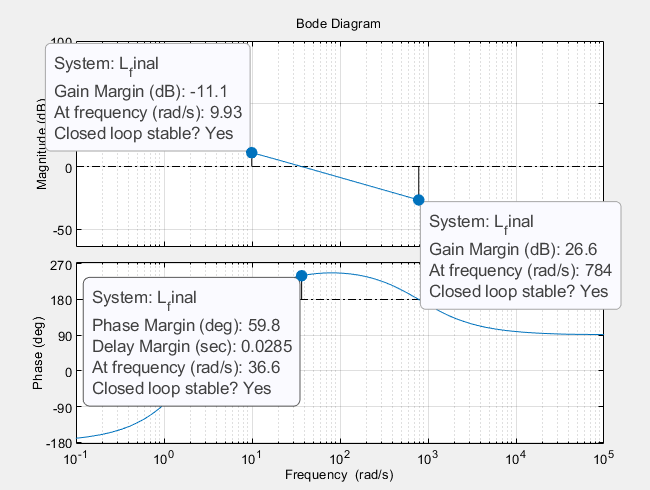

Se puede notar que hay dos margenes de ganancia. En este tipo de casos, se elige el de menor valor, que es -11.1dB.

Para calcular el márgen de estabilidad, basta con graficar el diagrama de bode de S y observar su valor máximo en el diagrama de magnitud. 

% S_transf = 1 - T_transf;  
% figure()
% bode(S_transf,optionss);title('S');

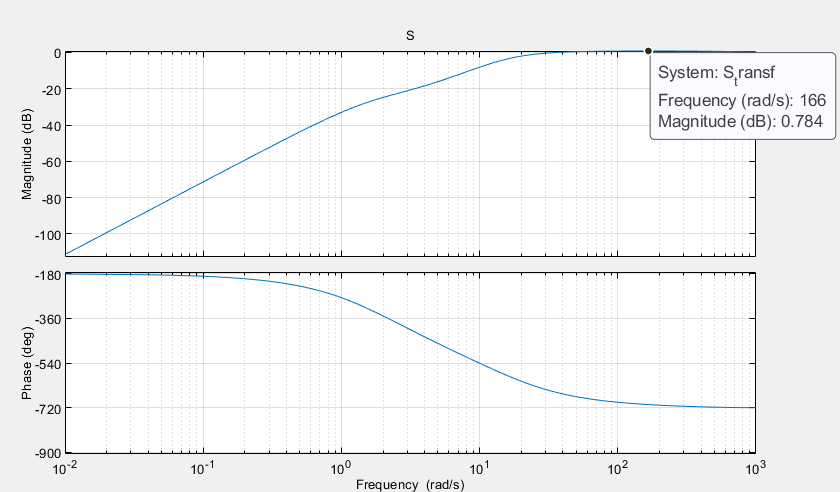

Se nota que el valor máximo es de 0,784dB. El margen de estabilidad se calcula como 1/sobrepico.

s_m = 1/db2mag(0.784)

s_m = 0.9137

Esto da como resultado un margen de estabilidad s_m = 0.9137